Images with different resolutions, Image histograms, binary images

09/06/2024

Instructions: 

1) Take 2 images, each with a different resolution. 

2) Take 2 images, each with a different filter color.

3) Create histograms of each of the 4 images that you have from step 1 and step 2

4) Use the information in these histograms to choose your thresholds

5) Create binary images using the thresholds you have chosen in step 4. 

6) Write a brief reflection. 

        6a. Give reasoning behind your choice of threshold

        6b. Do you think the binary version of your image allows you to carry out processes such as image  segmentation, feature detection more easily or does it make it more difficult, for  your specific images? 

% import images
lowres = imread('images/IMAGE006.jpg');
highres = imread('images/IMAGE008.jpg');
filter_blue = imread('images/IMAGE012.jpg');
filter_purple = imread('images/IMAGE011.jpg');

% Convert to grayscale
lowres = rgb2gray(lowres);
highres = rgb2gray(highres);
filter_blue = rgb2gray(filter_blue);
filter_purple = rgb2gray(filter_purple);

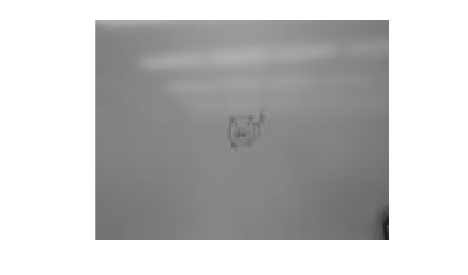

% Low Resolution Image
imshow(lowres)

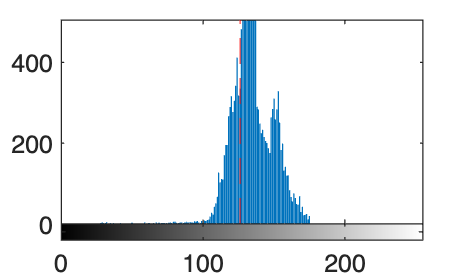

imhist(lowres)
threshold = 130;
xline(threshold, '--r')

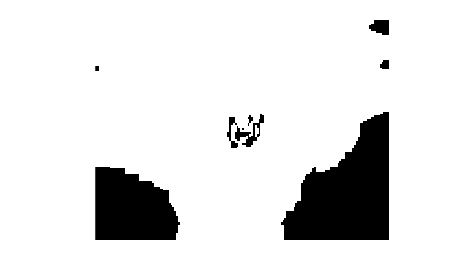

bw_lowres = imbinarize(lowres, threshold/255);
imshow(bw_lowres)

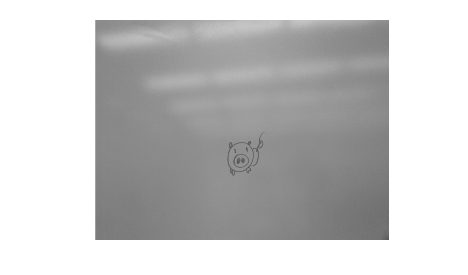

% High Resolution Image
imshow(highres)

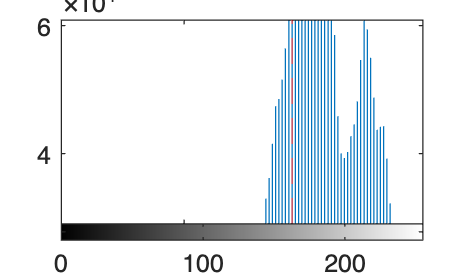

imhist(highres)
xline(133, '--r')

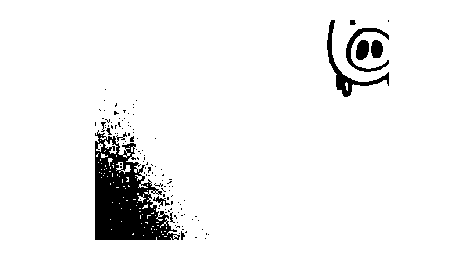

bw_highres = imbinarize(highres, 133/255);
imshow(bw_highres)

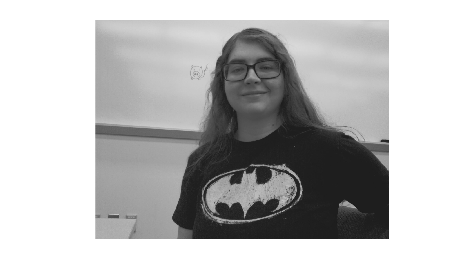

% Blue Filter Image
imshow(filter_blue)

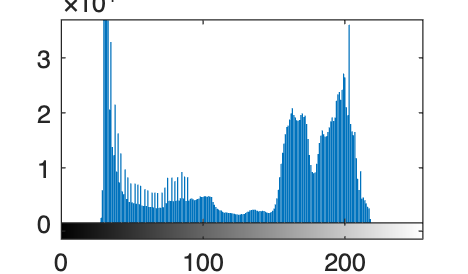

imhist(filter_blue)

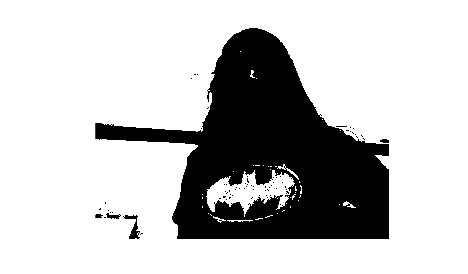

xline(150, '--r')
bw_blue1 = imbinarize(filter_blue, 150/255);
imshow(bw_blue1)

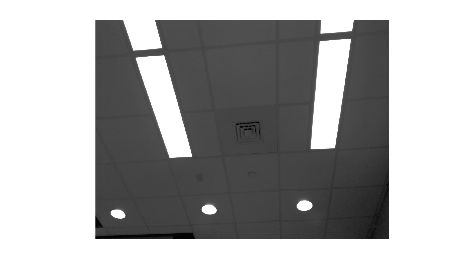

% Purple Filter Image
imshow(filter_purple)

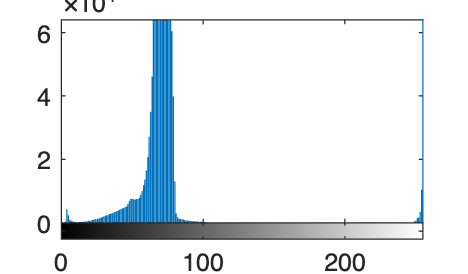

imhist(filter_purple)

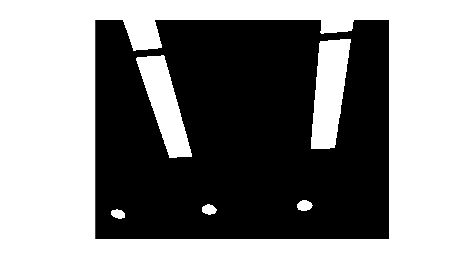

xline(150, '--r')
bw_purple = imbinarize(filter_purple, 150/255);
imshow(bw_purple)